mass = 0:0.05:1;
wbys = 30.6*((mass.*9.8).^(0.33));
b = 1.704.*(mass.^(1/3));
typ = 2;
S = mass.^0.71;
cmean = S./b;
ar = (b.^2)./S;
wingbeat_freq_max = mass.^(-1/3);
wingbeat_freq_min = mass.^(-1/6);
I = (b./2).^5;
wbys %wing loading

wbys =          0   24.1817   30.3967   34.7485   38.2090   41.1288   43.6793   45.9588   48.0293   49.9328   51.6995   53.3514   54.9055   56.3751   57.7708   59.1012   60.3734   61.5934   62.7662   63.8962   64.9869


b %wingspan

b =          0    0.6278    0.7909    0.9054    0.9965    1.0735    1.1407    1.2009    1.2555    1.3058    1.3525    1.3961    1.4372    1.4761    1.5130    1.5482    1.5819    1.6141    1.6452    1.6751    1.7040


S  %wing area

S =          0    0.1192    0.1950    0.2600    0.3190    0.3737    0.4254    0.4746    0.5218    0.5673    0.6113    0.6541    0.6958    0.7365    0.7763    0.8153    0.8535    0.8910    0.9279    0.9642    1.0000


cmean %mean ac

cmean =        NaN    0.1899    0.2465    0.2872    0.3201    0.3481    0.3729    0.3952    0.4156    0.4344    0.4520    0.4685    0.4841    0.4990    0.5131    0.5266    0.5395    0.5520    0.5640    0.5756    0.5869


ar %aspect ratio

ar =        NaN    3.3061    3.2083    3.1524    3.1133    3.0834    3.0591    3.0388    3.0212    3.0058    2.9922    2.9798    2.9686    2.9583    2.9488    2.9400    2.9318    2.9241    2.9169    2.9101    2.9036


flap_freq = ((mass.*9.832).^0.5).*((b).^(-17./24)).*((S).^(-1./3)).*((I).^(-1./8)).*((1.225).^(3./8));
flap_freq %Flapping frequency

flap_freq =        NaN    4.4108    3.8905    3.6150    3.4315    3.2956    3.1885    3.1007    3.0266    2.9628    2.9068    2.8570    2.8123    2.7719    2.7349    2.7010    2.6696    2.6404    2.6132    2.5878    2.5638


V = 20;
afp = (3.34.*(10.^-3)).*(mass.^(2/3));
h0 = 152.4;
Ta = 15 - (0.0065.*h0);
p = 1013.*((1-(h0.*2.26.*(10.^(-5)))).^5.265);
rho = 1.226.*(p./1013)*(288./(Ta+273));
cl = ((mass.*9.8)/(0.5.*rho.*S.*(V.^2))).^(0.5);
cl %C_L

cl = 0.1910

D_parasitic = 0.5.*rho.*afp.*(V.^2);
D_profile = 0.5.*rho.*0.02.*S.*(V.^2);
D_induced = 0.5.*rho.*0.8.*(cl.^2).*S;
D_tot = D_parasitic + D_profile + D_induced;
D_tot %TOTAL DRAG

D_tot =          0    0.6876    1.1195    1.4890    1.8229    2.1328    2.4246    2.7024    2.9686    3.2251    3.4733    3.7142    3.9487    4.1775    4.4012    4.6201    4.8348    5.0456    5.2527    5.4564    5.6570


D_tot.*V %TOTAL POWER REQUIRED

ans =          0   13.7527   22.3906   29.7793   36.4584   42.6550   48.4926   54.0476   59.3716   64.5016   69.4653   74.2839   78.9743   83.5504   88.0233   92.4026   96.6962  100.9111  105.0533  109.1278  113.1394


D_tot.*V.*(60.*45) %Total energy required

ans = 	1.0e+05 *

         0    0.3713    0.6045    0.8040    0.9844    1.1517    1.3093    1.4593    1.6030    1.7415    1.8756    2.0057    2.1323    2.2559    2.3766    2.4949    2.6108    2.7246    2.8364    2.9465    3.0548


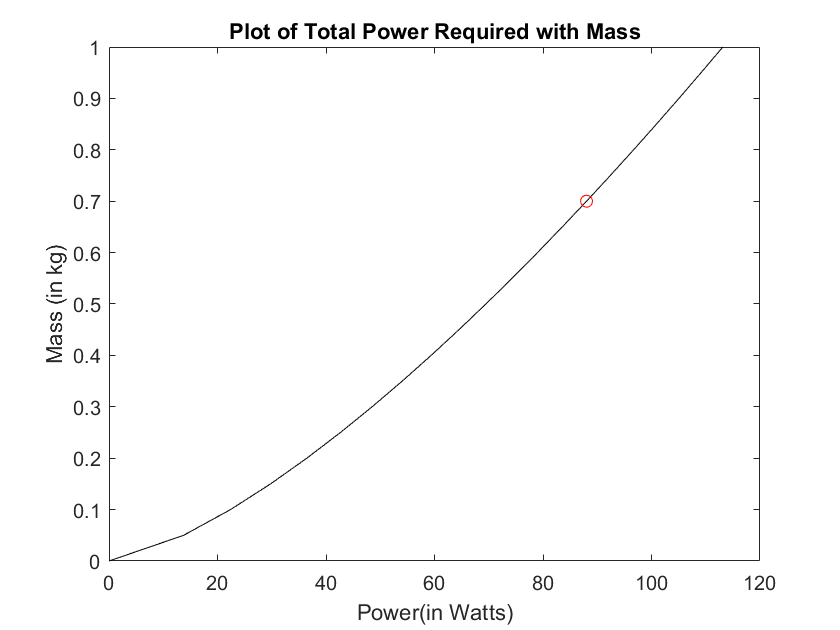

plot(D_tot.*V,mass, 'k' )%Plot of Mass vs Tot power reqd
hold on
title ('Plot of Total Power Required with Mass')
xlabel('Power(in Watts)')
ylabel('Mass (in kg)')
k = D_tot.*V;
plot(k(15),mass(15), 'ro')